syms w t k rho R a T g real positive
syms x y real
phi_I = a*w/k * exp(-k*T) * 1i * exp(1i*(w*t - k*x));
integrand_pressure = rho * diff(phi_I,t);
integrand_gamma = simplify(integrand_pressure / (a*exp(1i*w*t)));

x_min = -sqrt(R^2-y^2);
x_max = sqrt(R^2-y^2);
inner_int = int(integrand_gamma,x,x_min,x_max);

coeffs = rho*w^2*exp(-T*k)/k^2;
inner_int_without_coeffs = inner_int / coeffs;

y_min = -R;
y_max = R;
gamma_without_coeffs = int(inner_int_without_coeffs,y,y_min,y_max);
gamma_without_coeffs = simplify(rewrite(gamma_without_coeffs,'sin'));
coeffs = subs(coeffs,k^2,k*w^2/g);
gamma = abs(gamma_without_coeffs * coeffs)

$$gamma = \frac{2\,g\,\rho \,{\mathrm{e}}^{-T\,k}\,\left|\int_{-R}^{R}\sin\left(k\,\sqrt{R^{2}-y^{2}}\right)\mathrm{d}y\right|}{k}$$


%%


% syms r theta
% integrand_gamma_polar = r * subs(integrand_gamma,x,r*cos(theta));
% inner_int = int(integrand_gamma_polar,r,0,R);
% gamma = int(inner_int, theta, 0, 2*pi)

% subscript _num is for numerical, so I don't overwrite symbolic vars
R_num = [3 6 10 12 15 18];
T_wave = 5:2:13;
w_num = 2*pi./T_wave;
[R_mesh,w_mesh] = meshgrid(R_num,w_num);
k_mesh = w_mesh.^2/9.8;
approx = 2.88*R_mesh.^2;
actual = 1./k_mesh .* vpa(subs(gamma_without_coeffs,{R,k},{R_mesh,k_mesh}))

$$actual = \left(\begin{array}{cccccc} -27.456427579563067769045082554402 & -100.38755708387784343736943064063 & -222.64863765048104331259328841443 & -271.44613990844984808344327301697 & -302.08866019108418283622864758718 & -263.38949053118092184705154699686\\ -28.059887209965376903380815093082 & -109.69217934845933328114315091522 & -288.35422173846814828608543725294 & -399.53892278083344266517046963644 & -580.73860291242441717508363271967 & -763.54254045689759629431794838001\\ -28.195730837907007183338175345062 & -111.84318147884921732783978311665 & -304.54576866656544172521235414953 & -432.54498515009265155193316667039 & -658.8129535811029672532327990362 & -919.26036076862161086095498846427\\ -28.239091847851733549574478201512 & -112.53416566067327177148262284493 & -309.82664385553719305553332549177 & -443.42345594310609949569726460709 & -685.05070810937310928153325969289 & -972.86198014069190086130268180395\\ -28.25626437622228600014064558155 & -112.8084081773707301219569069527 & -311.93326298197317313199821880302 & -447.77830932047392299312557449906 & -695.62250974213246455059762531546 & -994.6319304421291963273419211468 \end{array}\right)$$

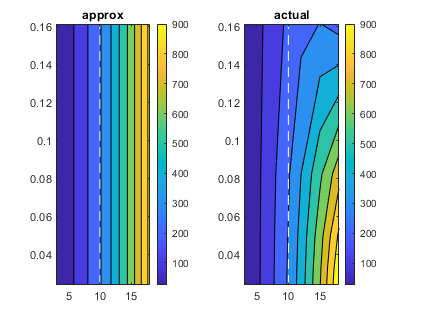

w_mesh = sqrt(k_mesh*9.8);
actual=abs(actual);
error = actual./approx;

figure
subplot 121
contourf(R_mesh,k_mesh,approx)
colorbar
title('approx')
hold on
plot([10 10],[min(k_num) max(k_num)],'w--')

subplot 122
contourf(R_mesh,k_mesh,actual)
colorbar
title('actual')
hold on
plot([10 10],[min(k_num) max(k_num)],'w--')

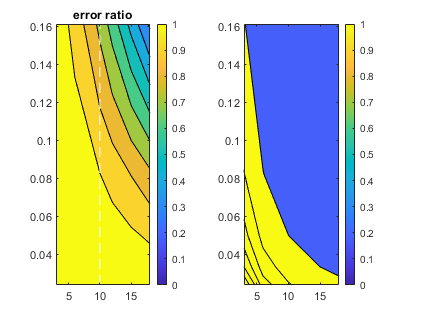


figure
subplot 121
contourf(R_mesh,k_mesh,error)
colorbar
caxis([0 1])
title('error ratio')
hold on
plot([10 10],[min(k_num) max(k_num)],'w--')

subplot 122
trial = 1./(k_mesh .* R_mesh); %exp(-w_mesh.^2*0.5
contourf(R_mesh,k_mesh,trial/2)
colorbar
caxis([0 1])

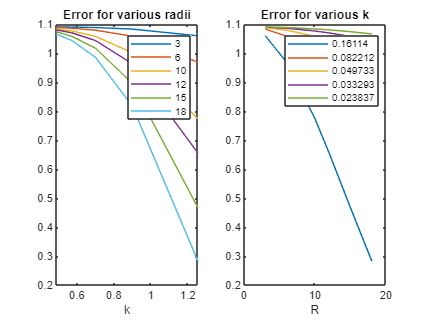

% line for each R
figure
subplot 121
for i=1:length(R_num)
plot(w_num,error(:,i),'DisplayName',num2str(R_num(i)))
hold on
end
title('Error for various radii')
xlabel('k')
legend

% line for each k
subplot 122
for i=1:length(k_num)
plot(R_num,error(i,:),'DisplayName',num2str(k_num(i)))
hold on
end
title('Error for various k')
xlabel('R')
legend

% compare numerical integral to actual wamit
w_wamit = hydro.w;
gamma = hydro.ex_ma(3,1,:);
gamma = gamma(:)';
draft = 2;
wamit_compare = gamma ./ exp(-w_wamit.^2*draft/9.8)

wamit_compare =   285.4498  285.2272  284.8560  284.3294  283.6444  282.7970  281.7825  280.5997  279.2419  277.7119  276.0053  274.1208  272.0601  269.8245  267.4122  264.8256  262.0639  259.1334  256.0349  252.7733  249.3532  245.7843  242.0787  238.2450  234.2968  230.2492  226.1167  221.9174  217.6684  213.3889  209.0942  204.8011  200.5256  196.2810  192.0807  187.9347  183.8523  179.8424  175.9094  172.0592  168.2943  164.6165  161.0274  157.5265  154.1137  150.7871  147.5457  144.3868  141.3083  138.3079


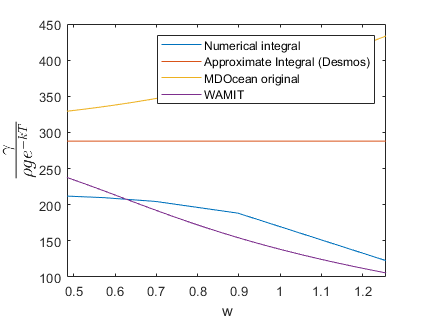

mdocean = 314 * exp(w_wamit.^2*draft/9.8);

figure
plot(w_num,actual(:,R_num==10)-100)
hold on
plot(w_num,approx(:,R_num==10))
plot(w_wamit,mdocean)
plot(w_wamit,wamit_compare)
legend('Numerical integral','Approximate Integral (Desmos)','MDOcean original','WAMIT')
xlim([min(w_num) max(w_num)])
xlabel('w')
ylabel('$\frac{\gamma}{\rho g e^{-kT}}$','Interpreter','latex','FontSize',20)

figure
plot(w_wamit,gamma)

Unrecognized function or variable 'w_wamit'.

hold on
fudge_factor = 1;
plot(w_num,actual(:,R_num==10) .* exp(-k_num'*fudge_factor*draft))
legend('WAMIT','Numerical Integration with 5x fudge')
xlim([min(w_num) max(w_num)])
xlabel('w')
ylabel('\gamma/\rho g')